# Rocket Model

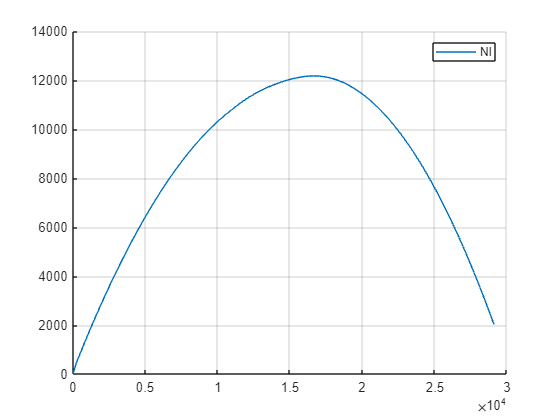

clear

tspan = linspace(0,100,100);

phi = -0.2;
Ft = 2500000;
%u1 = Ft*sin(phi)
%u2 = Ft*cos(phi)

x0 = [0 0 0 0 0 0];
[t,y] = ode23t(@(t,X) nonlinear(t,X,phi,Ft),tspan,x0);

%[t1,y1] = ode23t(@(t1,X1) linear(t1,X1,phi,Ft),tspan,x0);

figure
hold on
plot (y(:,1),y(:,3));
%plot (y1(:,1),y1(:,3));
hold off
grid on;
legend(["Nl" "L"])

function X_dot  = nonlinear(~,X, phi, Ft)

g = 9.81;
l = 100;
M = 1000;

X_dot = [X(2); (Ft*sin(phi)*cos(X(5)) - sin(X(5))*Ft*cos(phi))/M; X(4); (Ft*cos(phi)*cos(X(5)) + Ft*sin(phi)*sin(X(5)))/M - g; X(6); 6*(Ft*sin(phi)/(M*l))];

end

function X_dot  = linear(~,X, phi, Ft)

g = 9.81;
l = 100;
M = 1000;

Ft0 = Ft;
theta0 = 0;
phi0 = phi;
d = theta0-phi0;

A = [0 1 0 0 0 0; 0 0 0 0 Ft0*cos(d)/M 0; 0 0 0 1 0 0; 0 0 0 0 -Ft0*sin(d)/M 0; 0 0 0 0 0 1; 0 0 0 0 0 0];
B = [0 0; sin(d)/M Ft0*cos(d)/M; 0 0; cos(d)/M -(Ft0*sin(d)/M)-g; 0 0; -(6/M*l)*sin(phi0) -6*(Ft0/M*l)*cos(phi0)];

X_dot = A*X + B*[Ft; phi];

end